# Exercici 3 de Laboratori

**Exercici 1**

La lògica ens diu que integrar una imatge i després derivar-la ens deixaria la imatge original inalterada. Comproveu si és així al utilitzar dues finestres de convolució, una de integrativa i un altre de derivativa. I a l’inrevés?

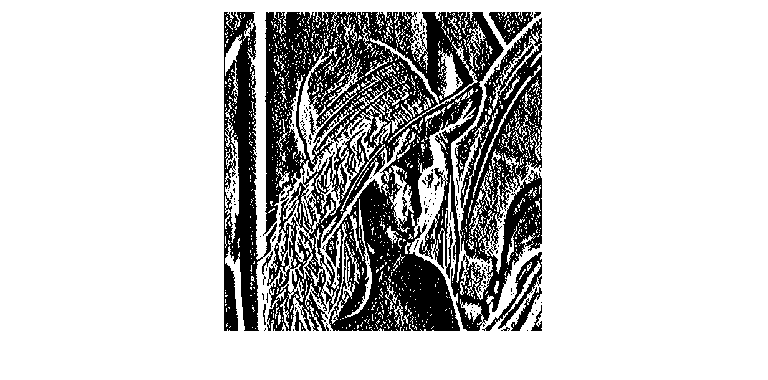

I = imread('lena_gray_512.tif');
h = [1 1 1; 1 1 1; 1 1 1];
h = h/sum(sum(h)); 
J = imfilter(I,h);

hx = [1, -1];
Gx = imfilter(double(J),hx);
imshow(Gx)

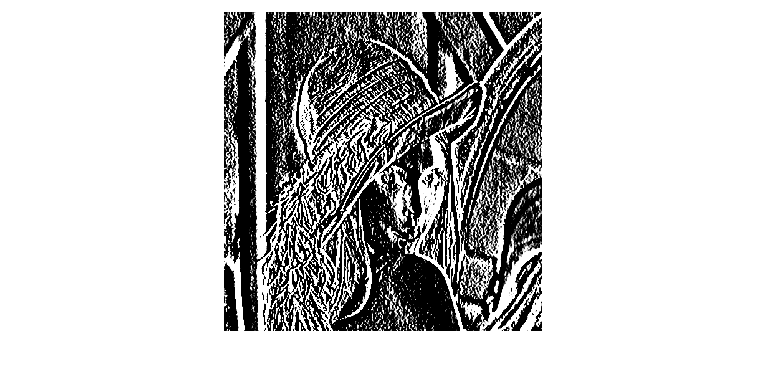


L = imfilter(double(I), hx);
M = imfilter(L, h);
imshow(M)

**Exercici 2**

Enaltiu (*contour enhancement*) els contorns d’una imatge RGB. El resultat haurà de ser una imatge en nivells de gris combinant els tres canals.

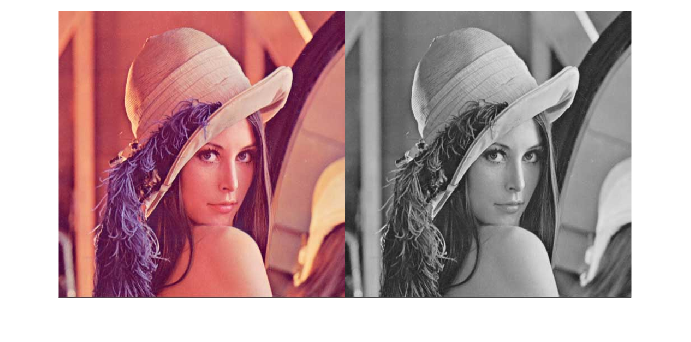

I2 = imread('lennacolor.tif');
black_white = rgb2gray(I2);
montage({I2, black_white})

**Exercici 3**

Quant una part de la imatge està desenfocada presenta els contorns borrosos o suavitzats. En base a aquest fet, fer una funció que mesuri un possible valor l’enfoc en la part central d’una imatge. Així, amb aquesta funció podrem decidir si una imatge està més ben enfocada que una altra (sistema d’auto-focus). Proveu amb dues imatges extretes d’internet (cerqueu les paraules clau  *focus stacking*)

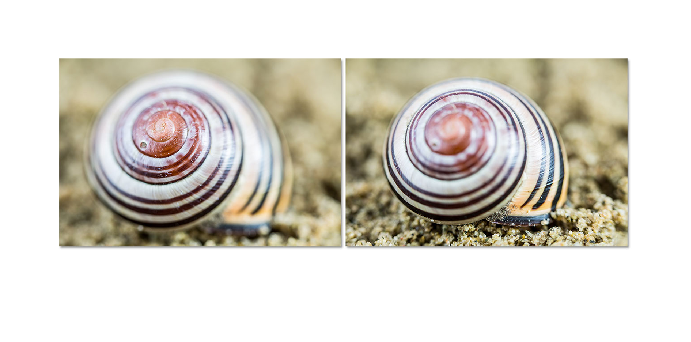

s1 = imread('shel.jpg');
s2 = imread('shell2.jpg');
montage({s1, s2})

focus = focusStacking(s1);
focus2 = focusStacking(s2);
%la imatge shel està més ben enfocada que la imatge shell2

**Exercici 4**

Suavitzar una imatge per després redimensionar-la a la meitat dona un millor aspecte visual que directament redimensionar-la a la meitat. Mesureu si la relació senyal soroll millora al fer aquest procés comparant amb el de directament redimensionat sense filtrar. Per fer-ho, torneu les imatges processades a la seva mida original i calculeu el SNR.

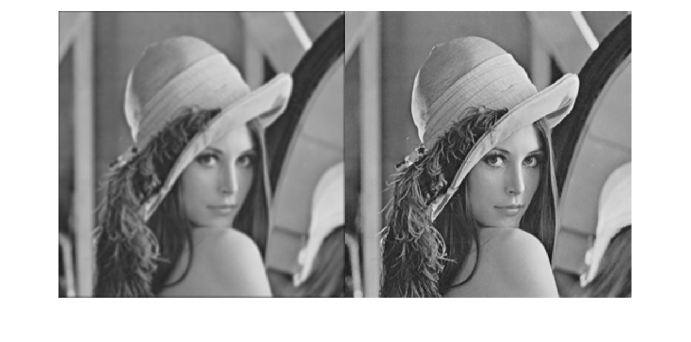

%suavitzar y després redimensionar
I = imread('lena_gray_512.tif');
h = fspecial('gaussian',10,10/5);
J = imfilter(I,h);

minimificationFactor = 0.5;
L = imresize(J,minimificationFactor);

%directamente redimensionar
K = imresize(I, minimificationFactor);

montage({L, K})


L = imresize(L, 2);

K = imresize(K, 2);

L = double(L(:));
Lma = max(L(:));
Lmi = min(L(:));
Lms = std(L(:));
snrL = 10*log((Lma-Lmi)./Lms)

snrL = 15.2022


K = double(K(:));
Kma = max(K(:));
Kmi = min(K(:));
Kms = std(K(:));
snrK = 10*log((Kma-Kmi)./Kms)

snrK = 15.6414


%El SNR de la imatge que primer es suavitza i després es redimensiona es
%menor que la imatge que directament redimensiona

function focus = focusStacking(x)
    focus = sum(x(:))/numel(x); 
end